Plot Rosenbrock's function  

tic

fsurf(@(x,y) log(1+100*(x.^2-y).^2+(1-x).^2), [0,2])
title ('log(1+100*(x.^2-y).^2+(1-x).^2)')
view(-13, 78)
hold on
h1 = plot3(1,1,0.1,'r*', 'MarkerSize',12)

h1 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '*'
         MarkerSize: 12
    MarkerFaceColor: 'none'
              XData: 1
              YData: 1
              ZData: 0.1000

  Show all properties


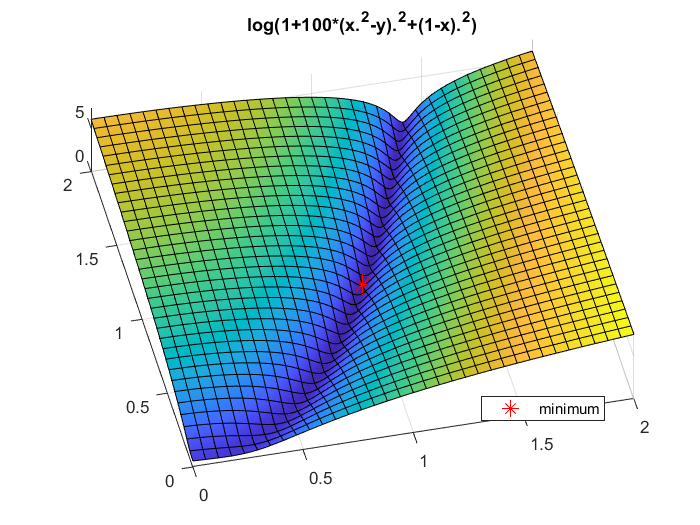

legend(h1, 'minimum', "Location","best")
hold off


toc

Elapsed time is 0.291770 seconds.


Simple fitness

tic

clear
rng default % for reproduceability
VFitnessFunction =   @simple_fitness;
NumberOfVariables = 2 ;
lb = [-3, 3] ;
ub = [3,3] ;
[x,fval] = ga(VFitnessFunction, NumberOfVariables, [], [], [], [], lb, ub) 

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     1.7314    3.0000


fval = 0.5355


toc

Elapsed time is 0.088537 seconds.


Paramaterized fitness

tic 

clear
rng default % for reproduceability

a = 100 ;
b = 1 ;
NumberOfVariables = 2 ;
lb = [-3, 3] ;
ub = [3,3] ;
VFitnessFunction = @(x)paramaterized_fitness (x, a, b);
[x,fval] = ga(VFitnessFunction, NumberOfVariables, [], [], [], [], lb, ub)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     1.7314    3.0000


fval = 0.5355


toc

Elapsed time is 0.081981 seconds.


Vectorized fitness

tic

clear
rng default % for reproduceability

options = optimoptions(@ga, 'UseVectorized', true) ;
a = 100 ;
b = 1 ;
NumberOfVariables = 2 ;
lb = [-3, 3] ;
ub = [3,3] ;
VFitnessFunction = @(x) vectorizedfitness (x, a, b);
[x,fval] = ga(VFitnessFunction, NumberOfVariables, [], [], [], [], lb, ub,[],  options)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     1.7314    3.0000


fval = 0.5355


toc

Elapsed time is 0.069389 seconds.


Constrained Minimization Using the Genetic Algorithm  

tic
clear
rng default % for reproduceability

options = optimoptions (@ga, 'MutationFcn', @mutationadaptfeasible)

options =   ga options:

   Set properties:
                     MutationFcn: @mutationadaptfeasible

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
                  MaxGenerations: '100*numberOfVariables'
             MaxStallGenerations: 50
                    MaxStallTime: Inf
                         MaxTime: Inf
    NonlinearConstraintAlgorithm: 'au

options = optimoptions (options, 'PlotFcn', {@gaplotbestf, @gaplotmaxconstr}, ...
    'Display','iter')

options =   ga options:

   Set properties:
                         Display: 'iter'
                     MutationFcn: @mutationadaptfeasible
                         PlotFcn: {@gaplotbestf  @gaplotmaxconstr}

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.8000
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
                  MaxGenerations: '100*numberOfVariables'
             MaxStallGenerations: 50
                    MaxStallTime: Inf
         


                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations


    1           2520       13578.1     0.000398      0


    2           4982       13578.2    5.343e-05      0


    3           7444       14023.2            0      0


    4          15957       13573.7    0.0009834      0
Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


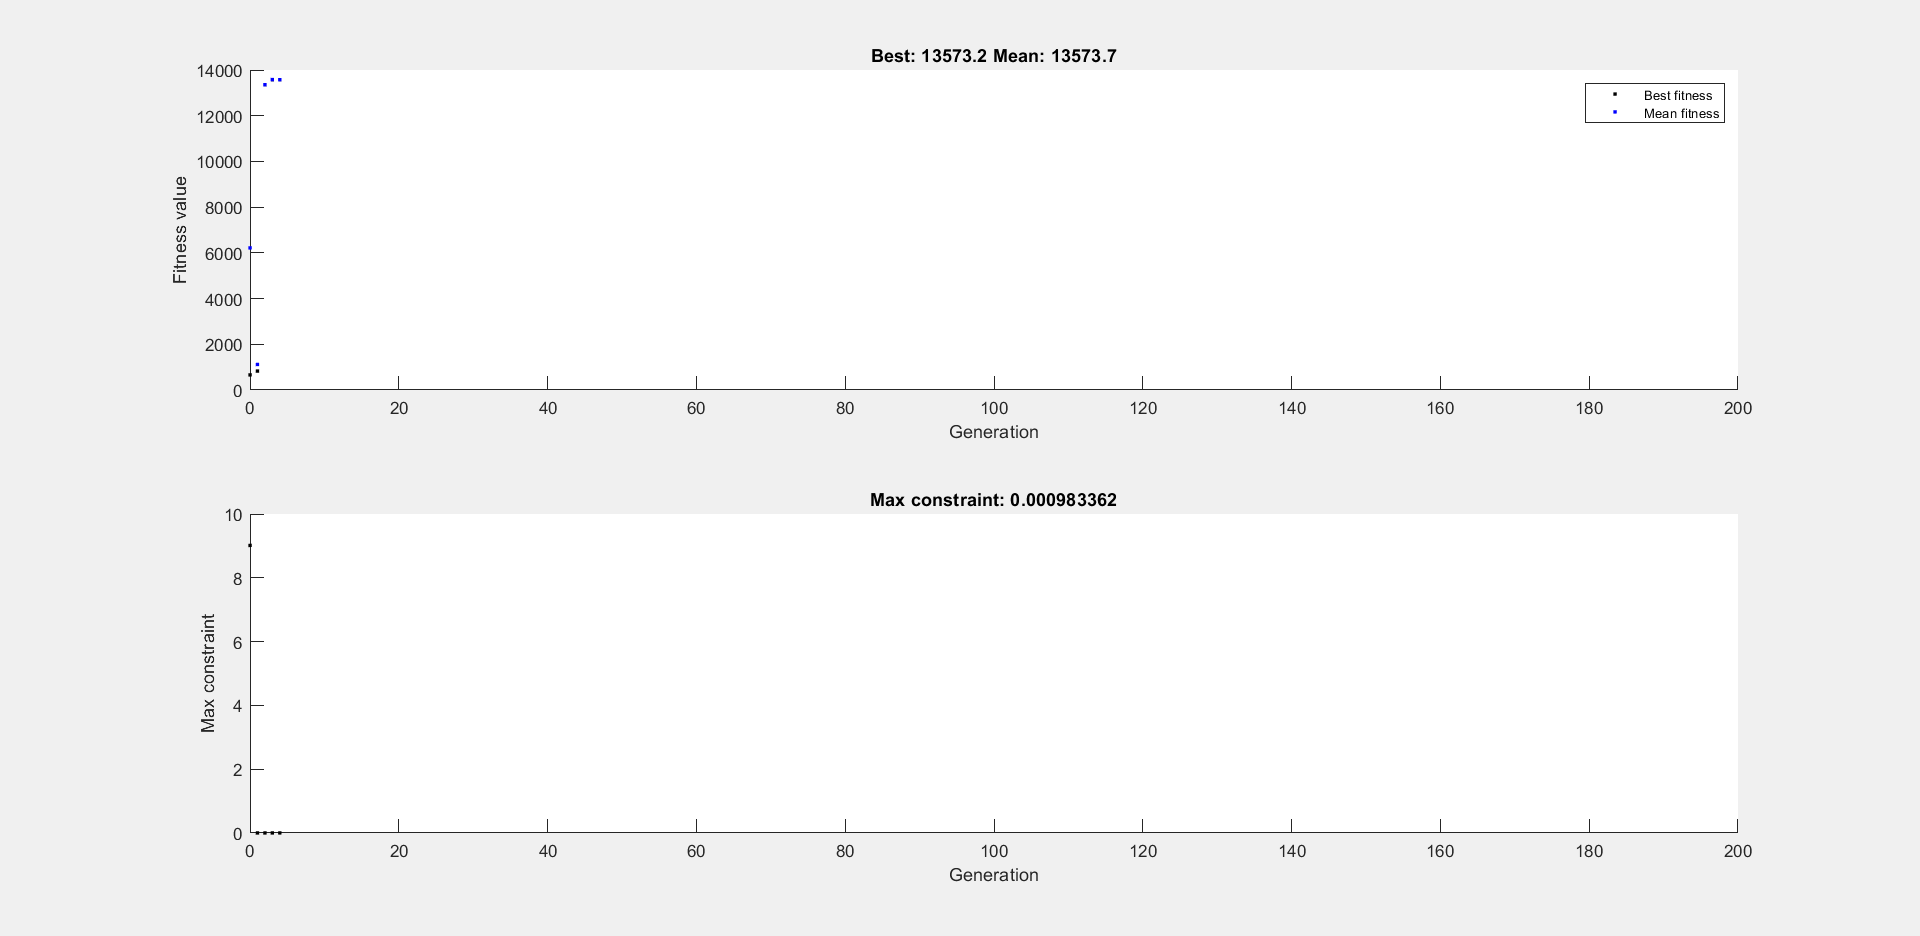

x =     0.8122   12.3104


fval = 1.3574e+04

ObjectiveFunction = @simple_fitness ;
nvars = 2;
lb = [0 0] ;
ub = [1 13] ;
ConstraintFunction = @simple_constraint ;
[x, fval] = ga(ObjectiveFunction, nvars, [], [], [], [], lb, ub, ConstraintFunction, options)


toc

Elapsed time is 4.128809 seconds.


Effect of GA options

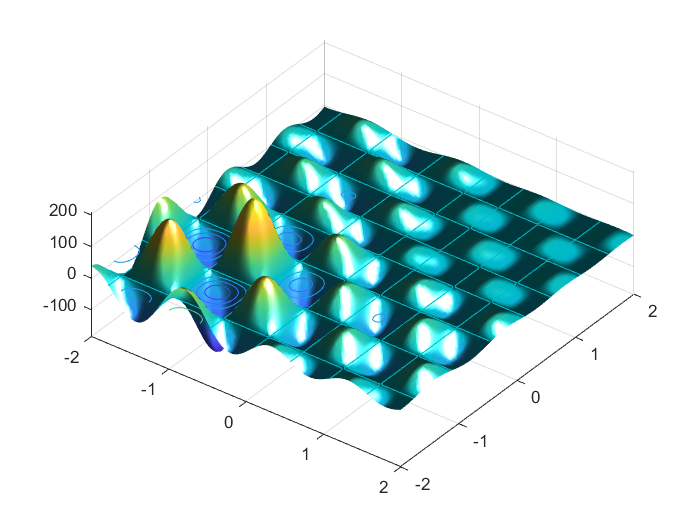

plotobjective (@shufcn, [-2 2,; -2 2])